# ROC

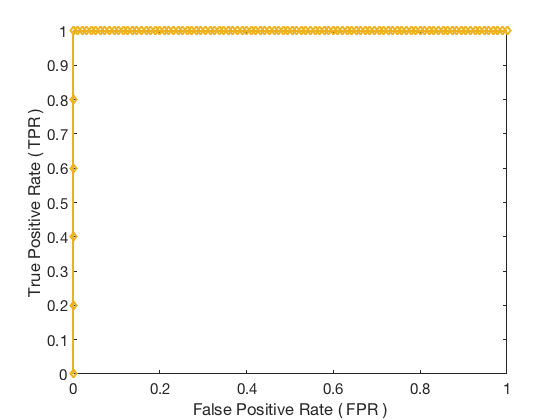

clearvars; close all; clc;

% rng(1)


N = 1000; %number of sampled points to use
d = 100;


A = randn(N,d);

x0 = zeros(d,1);
x0(randperm(d,5)) = randn(5,1);

% Add wighte gaussian noise to the function
f = A*x0;

f = awgn(f,100);

for n=1:3
    
tix = randperm(N,900)';
B = pinv(A(tix,:))*f(tix);


[B,ix] = sort(abs(B));

x = x0(ix);

for i=1:length(B)+1
    FP(i) = sum( and(~x,B) );
    TP(i) = sum( and( x,B) );
    B(i) = 0;  
end

FPR = FP./sum(~x);
TPR = TP./sum(~~x);

plot(FPR,TPR,'-d','LineWidth',2)
axis([0 1 0 1])
ylabel('True Positive Rate ( TPR )')
xlabel('False Positive Rate ( FPR )')
set(gca,'FontSize',15)
drawnow
hold on

FP = 0*FP;
TP = 0*TP;
end